% Question 1

PS1 = [1/2 1/4 1/8 1/16 1/32 1/32];
PS2 = [1/6 1/6 1/6 1/6 1/6 1/6];
H_S_1 = -sum(PS1.*log2(PS1));
H_S_2 = -sum(PS2.*log2(PS2));
disp(['Entropy for Source 1=',num2str(H_S_1)]);

Entropy for Source 1=1.9375


disp(['Entropy for Source 2=',num2str(H_S_2)]);

Entropy for Source 2=2.585



disp('Source-2 will be having a greater entropy.The graph of entropy which we know (downward parabola) is the reason why at equal probable case entropy is the largest here(1/6 equally likely)')

Source-2 will be having a greater entropy.The graph of entropy which we know (downward parabola) is the reason why at equal probable case entropy is the largest here(1/6 equally likely)


% Question 2 

% Part (a)


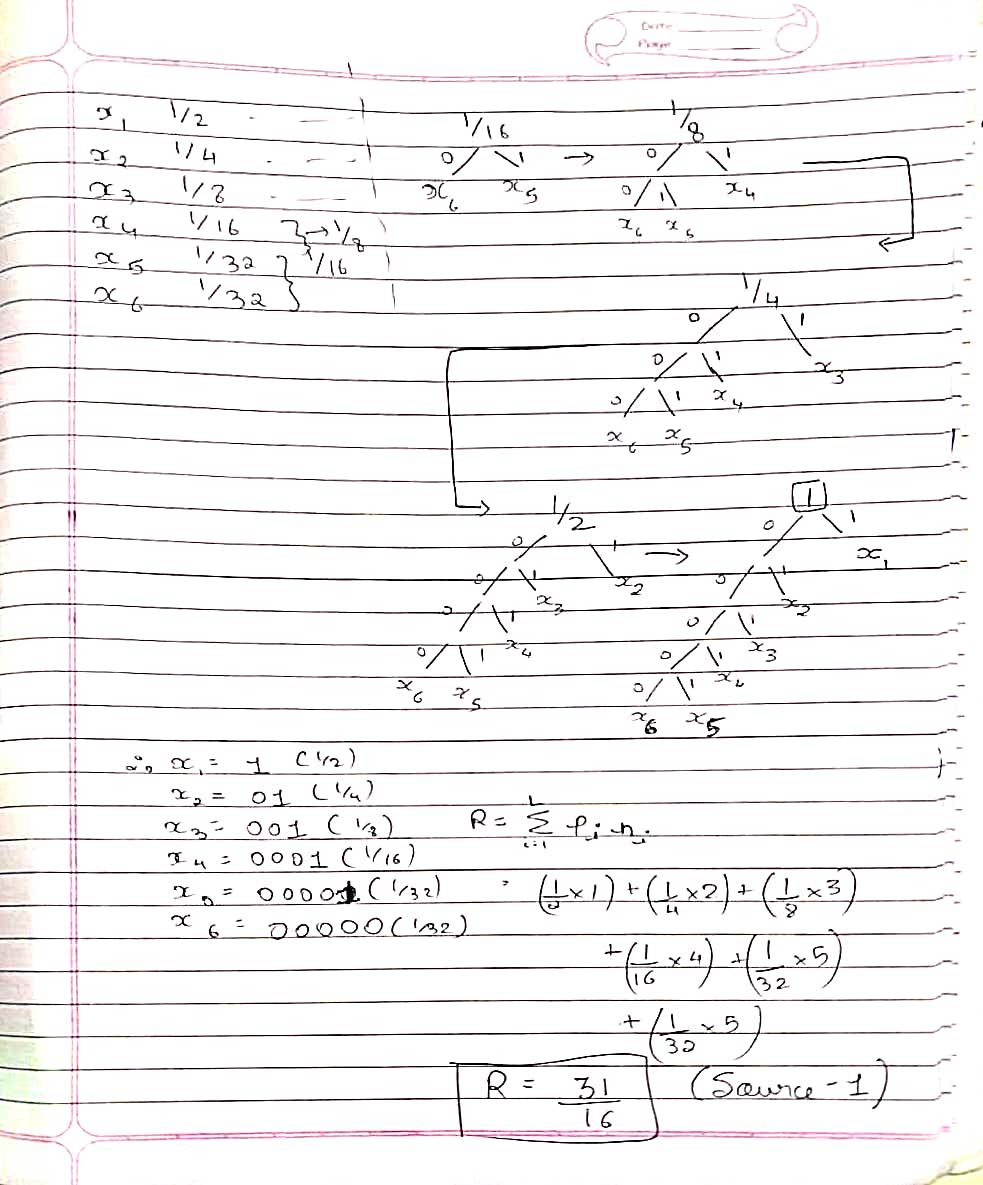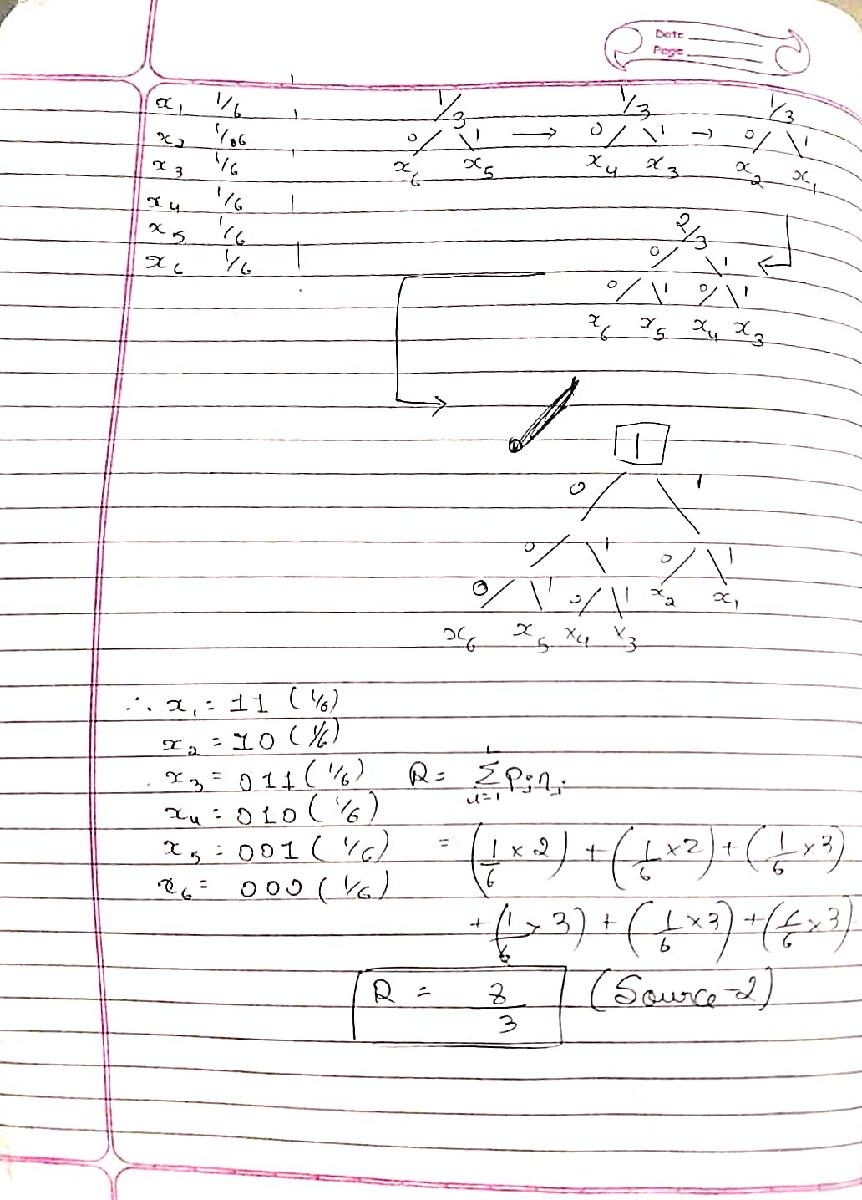


% Part (b)
load('discreteSources.mat')  %% The data file has been dowloaded locally and then loaded 
S1_arr = ["0" "10" "110" "1110" "11110" "11111"];
S1

S1 =      1     1     3     1     1     4     2     1     1     1     3     1     1     2     1     3     2     1     1     1     1     5     1     1     1     1     1     2     1     3     1     5     2     5     4     1     1     2     1     5     2     2     1     1     3     2     2     1     1     1


bit_str_1 = join(S1_arr(S1), '');
bit_str_1

bit_str_1 = "001100011101000011000100110100000111100000010011001111010111101110001001111010100011010100001000110111010010011001000000110110100100110010110100101000001000100111011110000110010111111011001001100100001011101100110000111010111001111100011101010010011010110110000110001001011101101110110110101111000101010010111001011010111011000011110110100111111111011000010010011001101000111000101010100000010001000000110101011001101101101101010010110001011101010010001101110101010011101001111100100110100001101000101001111000011101010011001110010000010011011111001000000011011001111110110000101111001111011100111000011000000101001110110110100011110100100010101111101101110101101010001111001010001001000000110110011011110000110101001100010110101011100110100101001000010011100001001111110101101101011100100001111011101000100000101110001011101011010100100000011001000111010110001000111110100111111010100100101111011001011010011001100100110101110000100000011001101110010100010010001000001010111000100000000

S2_arr = ["11" "10" "011" "010" "001" "000"];
S2

S2 =      2     5     5     2     4     5     3     5     3     1     5     5     6     2     3     3     4     1     3     2     4     3     5     3     6     3     3     6     2     3     5     5     3     5     3     1     3     1     3     2     4     6     5     3     3     2     3     2     1     5


bit_str_2 = join(S2_arr(S2), '');
bit_str_2

bit_str_2 = "100010011001000101100101111001001000100110110101101110010011001011000011011000100110010010110010111101111011100100000010110111001110110010110000101111110001001111010001111110000100000010111110111101000101100111001001001011011100110011110010101101010010010011101001011010000000011011111001000001001000100000100001000011100001001101111000010110000100101001110010000110001000110110010000111000111001011000011101001101110101110111101011010011000011011001001011100010110010010001001000110000101000011000010011100110000111011000110000111011011001000001110110110000000111001001010111001100101101001001100000110011001011100100110001000100111001000010000000001101010110010010111110001001000010110011001010000000001001011011000010100011011110101001101010100110100100111101000111010001001000001010011110110010011001011100000000111101001111101100110011010010110000100000101000100101101010110011101011111000101110101110011010110000010111101011001101000011010010011101001010010010000010111011111100010

% Part (c)
disp('Calculating Menc/M and R for both the sources -> ');

Calculating Menc/M and R for both the sources -> 



disp('Source-1');

Source-1


M_enc_1 = strlength(bit_str_1);
disp(['Menc_1:',num2str(M_enc_1)]);

Menc_1:1935764


M_1 = 1e6;
disp(['M_1 :',num2str(M_1)]);

M_1 :1000000


R_S1_1 = M_enc_1/M_1;
disp(['Menc/M :',num2str(R_S1_1)]);

Menc/M :1.9358


R_1 = 31/16;
disp(['R_1(sum(pk*nk)) :',num2str(R_1)]);

R_1(sum(pk*nk)) :1.9375




disp('Source-2');

Source-2


M_enc_2 = strlength(bit_str_2);
disp(['Menc_2:',num2str(M_enc_2)]);

Menc_2:2666551


M_2 = 1e6;
disp(['M_2 :',num2str(M_2)]);

M_2 :1000000


R_S2_2 = M_enc_2/M_2;
disp(['Menc/M :',num2str(R_S2_2)]);

Menc/M :2.6666


R_2 = 8/3;
disp(['R_2(sum(pk*nk)) :',num2str(R_2)]);

R_2(sum(pk*nk)) :2.6667


% Part (d)

disp('Source-1');

Source-1


eta_S1_1 = H_S_1/R_S1_1;
disp(['Efficiency(Simulated):',num2str(eta_S1_1)]);

Efficiency(Simulated):1.0009


eta_S1_2 = H_S_1/R_1;
disp(['Efficiency(Theoretical):',num2str(eta_S1_2)]);

Efficiency(Theoretical):1


disp('Source-2');

Source-2


eta_S2_1= H_S_2/R_S2_2;
disp(['Efficiency(Simulated):',num2str(eta_S2_1)]);

Efficiency(Simulated):0.9694


eta_S2_2 = H_S_2/R_2;
disp(['Efficiency(Theoretical):',num2str(eta_S2_2)]);

Efficiency(Theoretical):0.96936


% Part (e)
% Now randomizing the codeword attached to random probability
disp('Now attaching random codeword with random probability');

Now attaching random codeword with random probability


S1_arr = ["10" "11110" "1110" "0" "11111" "110"];
S1

S1 =      1     1     3     1     1     4     2     1     1     1     3     1     1     2     1     3     2     1     1     1     1     5     1     1     1     1     1     2     1     3     1     5     2     5     4     1     1     2     1     5     2     2     1     1     3     2     2     1     1     1


bit_str_1 = join(S1_arr(S1), '')

bit_str_1 = "101011101010011110101010111010101111010111011110101010101111110101010101111010111010111111111011111010101111010111111111011110101011101111011110101010111101010111001111010111101011101011110101010101011101110111101011110101110101111011101111010111101111010101010111101010111101001111110101011101011110110111101110101111010111010111101010101111001110101110101010011110010110101010011110111101011110101110111101110111010101011101010111101011110011100111011101111011111101011110111101111010111100101111011101111001110101010111111110111101011011111111010101011110101111010111010111011110101001010111101111011110111101010101010111101010111101010101010111011110111101110101110111011101110111101111010111101110101011110011110111101011110101011100111101111011110100111101011010101111010111011110101010111011110101011110111101011111101010011110111101011101001011110101010101111010111011010101111010101010101011101110101101111011101010101111011111101111101001010101110101010101011110111101001110111

S2_arr = ["001" "011" "10" "11" "000" "010"];
S2

S2 =      2     5     5     2     4     5     3     5     3     1     5     5     6     2     3     3     4     1     3     2     4     3     5     3     6     3     3     6     2     3     5     5     3     5     3     1     3     1     3     2     4     6     5     3     3     2     3     2     1     5


bit_str_2 = join(S2_arr(S2), '')

bit_str_2 = "011000000011110001000010001000000010011101011001100111110000100101010010011100000001000010001100011001111010000101001110011001000100101100100100101001110001110000010010110100110100001000101100100111000100000010000000001010011100000010111101100111011111110011011110011101001010100010111101011110000100000101101000101101001110100010101100101011110111001111010001010011000011001000010100110000010001001010011011101001101100101100100111001111001010100000001001100010000000010011110000110100110110100010101110011100101001100101000101010011001100000100000011010010010100111111011001011100001011111001000001110000100111110010011000000001000010110100100000110110110010000001000101100000001011001000011110110100100000001010010110110000110010011101110110110111011111000111000001110000000100001110001100000000111100101101001010001111000101100100001110111100101011010110110000001011011001000001110010010110001001101100101110110010100001000111001000011011010001111110011011110111111010110010110010010

disp('Source-1');

Source-1


M_enc_1 = strlength(bit_str_1);
disp(['Menc_1:',num2str(M_enc_1)]);

Menc_1:3062207


R_S1_1 = M_enc_1/M_1;
disp(['Menc/M(S1) :',num2str(R_S1_1)]);

Menc/M(S1) :3.0622


R_S1_2=98/32;
disp(['R_1(sum(pk*nk)) :',num2str(R_S1_2)]);

R_1(sum(pk*nk)) :3.0625


disp('Source-2');

Source-2


M_enc_2 = strlength(bit_str_2);
disp(['Menc_2:',num2str(M_enc_2)]);

Menc_2:2666945


R_S2_1 = M_enc_2/M_2;
disp(['Menc/M(S2) :',num2str(R_S2_1)]);

Menc/M(S2) :2.6669


R_S2_2=8/3;
disp(['R_2(sum(pk*nk)) :',num2str(R_S2_2)]);

R_2(sum(pk*nk)) :2.6667


disp('Source-1');

Source-1


eta_S1_1 = H_S_1/R_S1_1;
disp(['Efficiency(Simulated):',num2str(eta_S1_1)]);

Efficiency(Simulated):0.63271


eta_S1_2 = H_S_1/R_S1_2;
disp(['Efficiency(Theoretical):',num2str(eta_S1_2)]);

Efficiency(Theoretical):0.63265


disp('Source-2');

Source-2


eta_S2_1 = H_S_2/R_S2_1;
disp(['Efficiency(Simulated):',num2str(eta_S2_1)]);

Efficiency(Simulated):0.96926


eta_S2_2 = H_S_2/R_S2_2;
disp(['Efficiency(Theoretical):',num2str(eta_S2_2)]);

Efficiency(Theoretical):0.96936
